## SECTION 1a – Assessing sensor noise, accuracy, and signal to noise ratio (SNR)

% Select a segment from your pinch data and create a new variable
%
% pinchSegment = outData( startSample:stopSample,:)
%
% The first argument startSample:stopSample indicates the rows to choose.
% The second argument, just the colon indicates "give me all the columns".
%
% Plot the data segment
% SOLUTION -- Plot the Segment Data
clc;close all;clear;

pname = pwd;
fname = 'data/data-1a.mat';
load(fullfile(pname, fname))

pinchSegment = outData(280:400,:);
plot(pinchSegment(:,1), pinchSegment(:,2))
grid on
%  Title the graph -- Use Descriptive titles
title('Pinch Segment Data A')
%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')
%  Label the Y-axis
ylabel('Signal')

% Compute the sensor measurement noise standard deviation
% widthChatter =
% distanceChatter =
% stdSamples =
% stdSensor =
% SOLUTION

widthChatter = (10 + 10 + 7) / 3;
distanceChatter = (27 + 38 + 33) / 3;
stdSamples = widthChatter / 6;
stdSensor = stdSamples / distanceChatter;

% stdTotal =
% SOLUTION

stdTotal = sqrt(stdSensor^2 + 0.29^2);

% Estimate the temperature drift of the signal by fitting a curve through
% your segment of data.
%
% Use the MATLAB polyfit command. You can try to use a linear fit (first
% order) or a quadratic fit (second order). This is an argument in the
% polyfit function
%
% coeffs = polyfit( xData, yData, order )
% Create an estimate of the drift and find the error by removing the drift estimate
% from the pinch segment data. Plot the error.
% Compute the standard deviation of the error.
% SOLUTION

coefficients = polyfit(pinchSegment(:,1), pinchSegment(:,2), 1);
slope = coefficients(1);
intercept = coefficients(2);

driftEstimate = slope * pinchSegment + intercept; % Calculate the drift estimate
errorEstimate = pinchSegment - driftEstimate; % Remove the drift from the original signal to find the error

figure;
plot(pinchSegment(:,1), pinchSegment(:,2))
grid on % Display or hide axes grid lines
hold on % Retain current plot when adding new plots

%  Title the graph -- Use Descriptive titles
title('Pinch Segment versus Drift Estimate')
%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')
%  Label the Y-axis
ylabel('Signal')

plot(pinchSegment,driftEstimate,'Color','r','LineWidth',2,'LineStyle','--');

% adding legend to show different lines
legend('Pinch Segment', 'Drift Estimate')
hold off

 

## Section 1b -  Oversample and Averaging to Reduce System Noise

% Capture another set of pinch data using oversampling and save the data in a file.
% Load the file and plot the data
%
% Estimate the temperature drift of the signal by fitting a curve through
% a selected portion of the data.
%
% Use the MATLAB polyfit command. You can try to use a linear fit (first
% order) or a quadratic fit (second order). This is an argument in the
% polyfit function
%
% coeffs = polyfit( xData, yData, order )
% Create an estimate of the drift and find the error by removing the drift estimate
% from the pinch segment data. Plot the error.
% Compute the standard deviation of the error.
% SOLUTION

clc;close all;clear;

pname = pwd;
fname = 'data/data-1b.mat';
load(fullfile(pname, fname))

pinchSegment = outData(280:400,:);
plot(pinchSegment(:,1), pinchSegment(:,2))
grid on
%  Title the graph -- Use Descriptive titles
title('Pinch Segment Data B')
%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')
%  Label the Y-axis
ylabel('Signal')

coefficients = polyfit(pinchSegment(:,1), pinchSegment(:,2), 1);
slope = coefficients(1);
intercept = coefficients(2);

driftEstimate = slope * pinchSegment + intercept; % Calculate the drift estimate
errorEstimate = pinchSegment - driftEstimate; % Remove the drift from the original signal to find the error

% Compute the standard deviation of the error estimate when using
% oversampling and averaging (OSA)
% SOLUTION

stdErrorOSA = std(errorEstimate);

 

## Section 1c – Adding Dithering Noise to Enable Oversampled Averaging

### Part 1

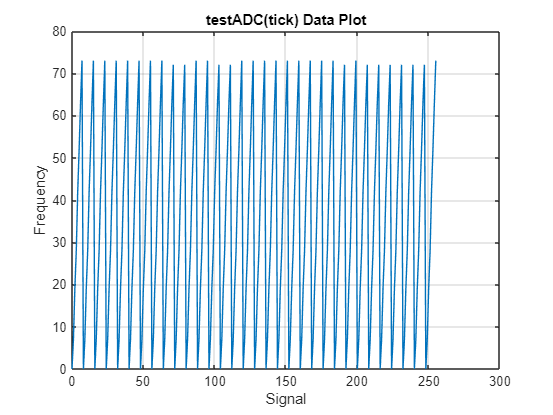

% Plot the 256 samples of the DAC voltage data
% Plot a histogram (both normal and cumulative) of the 256 sample data
% Plot the data and historgrams after changing the call parameter to testDAC() to
% random(256)
% Compute the typcial error (standard deviation) of the ramp data
% Compute the typcial error (standard deviation) of the random data
% SOLUTION

clc;close all;clear;

pname = pwd;
fname = 'data/data-1c(tick).mat';
load(fullfile(pname, fname))

samples = outData(:,1);
signal = outData(:,2);

figure;
plot(samples, signal)
grid on
title('testADC(tick) Data Plot')
xlabel('Signal')
ylabel('Frequency')

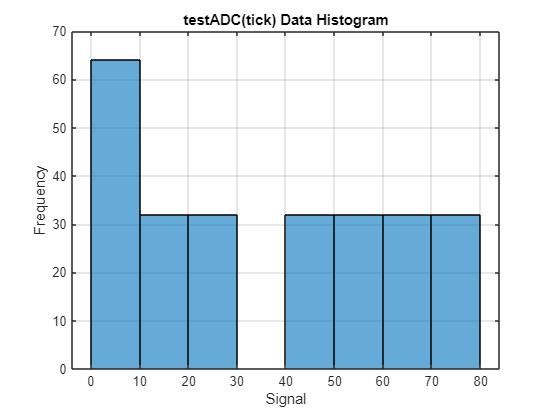


histogram(signal)
grid on
title('testADC(tick) Data Histogram')
xlabel('Signal')
ylabel('Frequency')

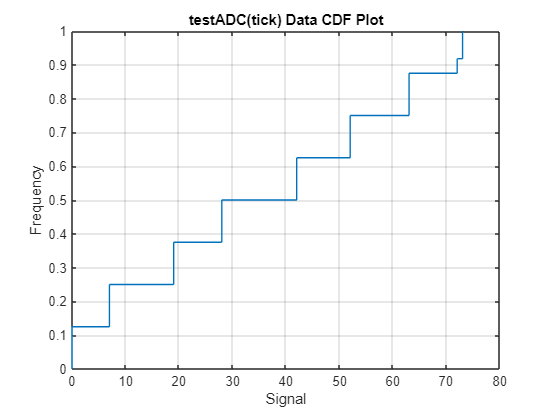


cdfplot(signal)
grid on
title('testADC(tick) Data CDF Plot')
xlabel('Signal')
ylabel('Frequency')

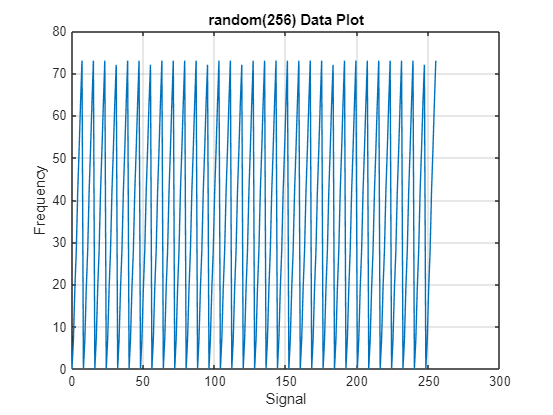


fname = 'data/data-1c(rand).mat';
load(fullfile(pname, fname))

samples = outData(:,1);
signal = outData(:,2);

figure;
plot(samples, signal)
grid on
title('random(256) Data Plot')
xlabel('Signal')
ylabel('Frequency')

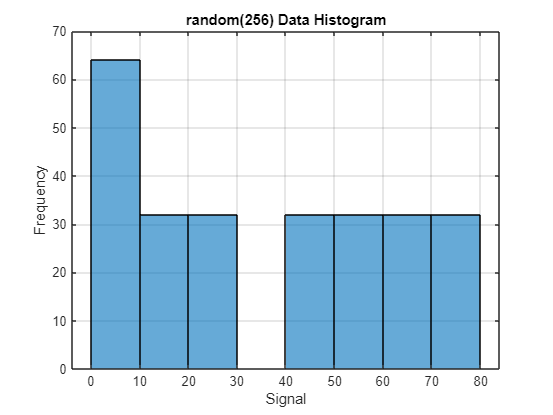


histogram(signal)
grid on
title('random(256) Data Histogram')
xlabel('Signal')
ylabel('Frequency')

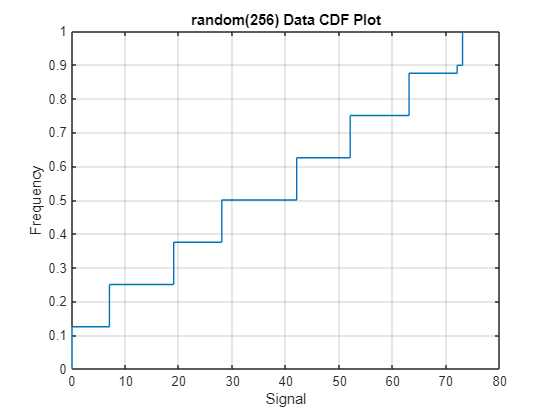


cdfplot(signal)
grid on
title('random(256) Data CDF Plot')
xlabel('Signal')
ylabel('Frequency')

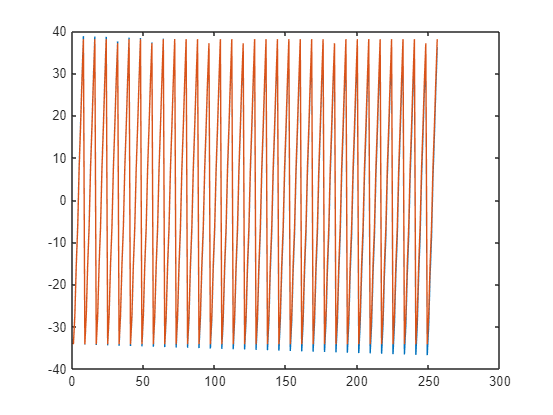


coefficients = polyfit(samples, signal, 1);
slope = coefficients(1);
intercept = coefficients(2);

driftEstimate = slope * outData + intercept; % Calculate the drift estimate
errorEstimate = signal - driftEstimate; % Remove the drift from the original signal to find the error
plot(errorEstimate);

stdErrorOSA = std(errorEstimate);

 

### **Part 2 - Dither Voltage Generator Hardware Description**

% Plot the data taken with the dither/averaging
% Plot the signal with the drift removed
% Plot a histogram of the signal with drift removed both the PMF and the CDF.
% Compute the standard deviation of the signal with drift removed.
%SOLUTION
clc;close all;clear;
load('data/data-1c(tick).mat');

pinchSegment = outData(1:50,:);

coefficients = polyfit(pinchSegment(:,1), pinchSegment(:,2), 1);
slope = coefficients(1);
intercept = coefficients(2);

driftEstimate = slope * pinchSegment + intercept; % Calculate the drift estimate
errorEstimate = pinchSegment - driftEstimate; % Remove the drift from the original signal to find the error
stdError = std(errorEstimate); % Find standard deviation of the error estimate

% Compute values for Table 1
% SOLUTION
% OSA only case
% Dither and OSA case

 

## Section 1d – Effective ADC Bit Depth from Dithering Noise and Averaging

% Compute the increase in the effective resolution (in bits) of the ADC by using dithering and averaging

% SOLUTION
